# Cell Visualization and Stats

## Load Data

### Required Variables

be sure to cd to the Lysosome Analysis folder

focus on 

close all
clearvars -except paths
[VL, idT, cellT, dyingT] = loadProjectTables(paths);
idT = sortrows(idT,["Type", "Health"])

idT = 35×8 table
               Cell                Type             Lysosome               Health      TasteBud      Source      Dataset        Folder     
    ___________________________    ____    ___________________________    _________    ________    __________    _______    _______________

    "TB1_AP16_EM"                  "I"     "TB1_AP16__LYS_RSL"            "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP34_EM"                  "I"     "TB1_AP34_lys_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP36_EM"                  "I"     "TB1_AP36_LYS_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_A

### Merge Cell Volumes

T = [cellT; dyingT];
T = sortrows(T,["Type","Volume"]);

### Remove duplicates

T = sortrows(T,"Cell","ascend");
T(41,:) = []; % remove duplicate TB3_TC01
T(26,:) = []; % remove duplicate "TB2_T2C-01_FR"

writetable(T,fullfile(paths.lysosome,"cell_volumes.csv"))

## Visualize Cells

### Type I cells

1. TB1_AP37_EM. healthy. 394.35
2. TB1_AP38_EM. healthy. 407.79
3. TB1_AP36_EM. healthy. 472.18
4. TB1_AP34_EM. healthy. 481.76
5. TB1_AP16_EM. healthy. 490.27
6. TB1_AP44_EM. early. 536.17
7. TB2 Nucleus_04_cw_cell-ry. healthy. 690.64
8. TB1_AP70_RSL. healthy. 866.79
9. TB2_T1C-06_cw. healthy. 1212.88
10. TB2_T1C-05_cw. healthy. 1634.00


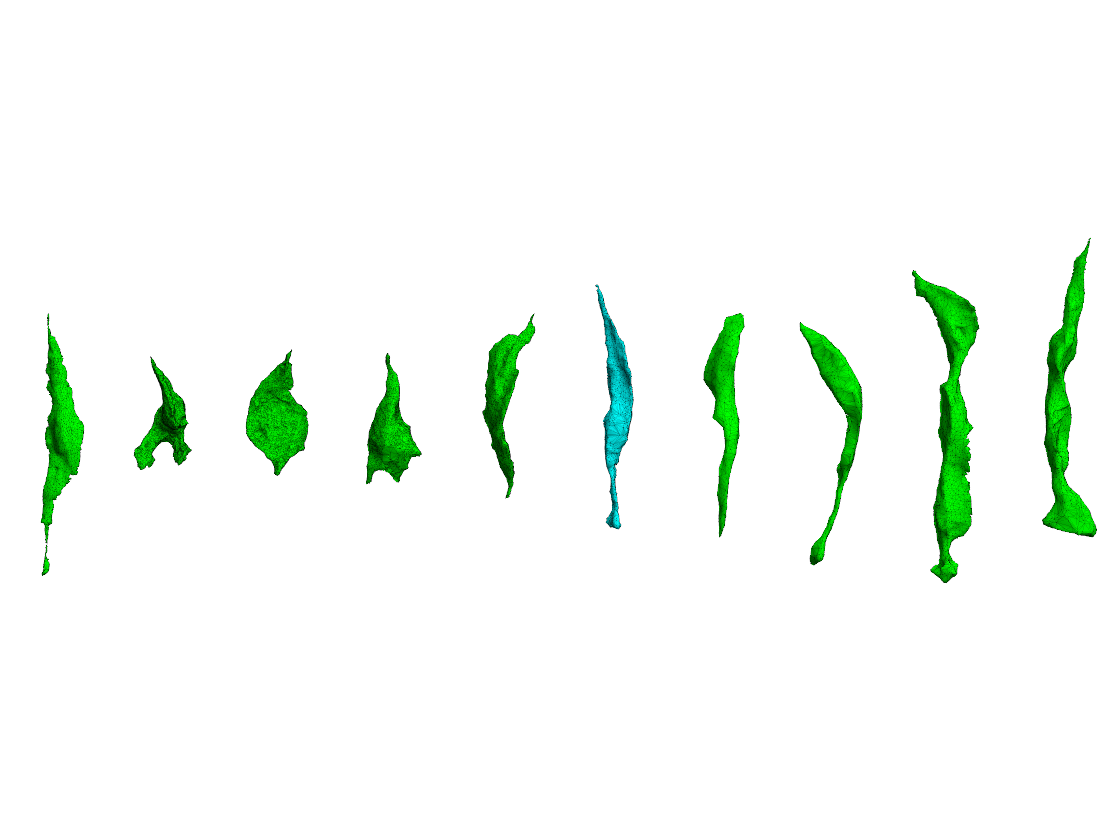

display_cell_by_type(T, "I")

### Type II

11. TB1_T2C11. early. 717.99
12. TB2_T2C-12_cw. healthy. 810.93
13. TB1_T2C05. early. 835.16
14. TB1_T2C06. early. 878.17
15. TB1_AP14_EM. healthy. 951.12
16. TB2_T2Cell03_CM_LES. healthy. 988.13
17. TB2_T2C-09_cw. healthy. 1054.02
18. TB1_AP51_EM. early. 1066.87
19. TB2_T2C-10_cw. healthy. 1173.65
20. TB3_TC02. early. 1301.09
21. TB1_AP43. early. 1336.08
22. TB1_AP40_EM. early. 1398.27
23. TB2_T2C-03_cw. early. 1408.91
24. TB2_T2_14. healthy. 1527.38
25. TB1_AP13_EM. early. 1543.46
26. TB3_TC04. early. 1677.04
27. TB3_TC05. early. 1854.52
28. TB2_T2C-01. early. 1980.73
29. TB2_T2C-01_FR. early. 1984.42


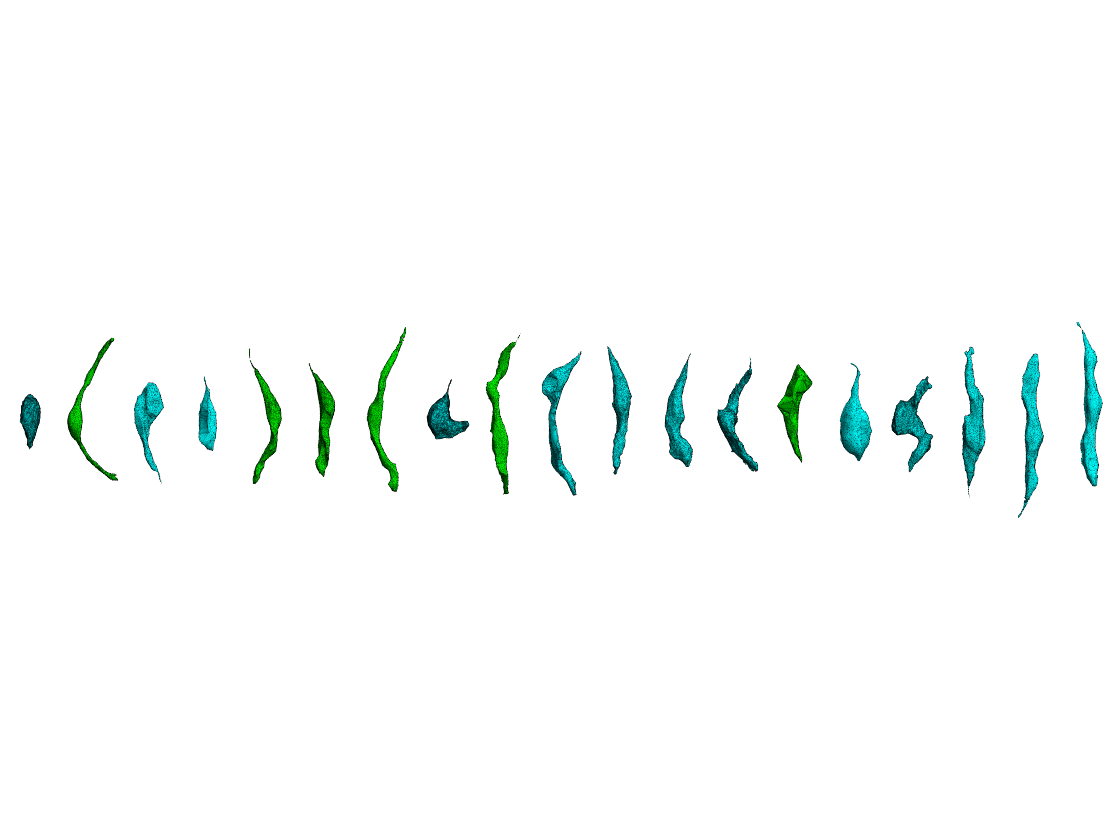

display_cell_by_type(T,"II")

### Type III

30. TB2_t3cell02_CM_RSL. healthy. 524.77
31. TB1_AP31_EM. healthy. 560.82
32. TB2_T3Cell07_cm_RSL. healthy. 577.43
33. TB2_T3C-17_cw. healthy. 616.43
34. TB2_T3C-08_cw. healthy. 664.30
35. TB1_AP02_EM. healthy. 674.29
36. TB2_T3C-14_FR. healthy. 810.45
37. TB1_AP68. early. 886.86
38. TB3_TC06. early. 1219.70
39. TB3_TC03. early. 1310.51


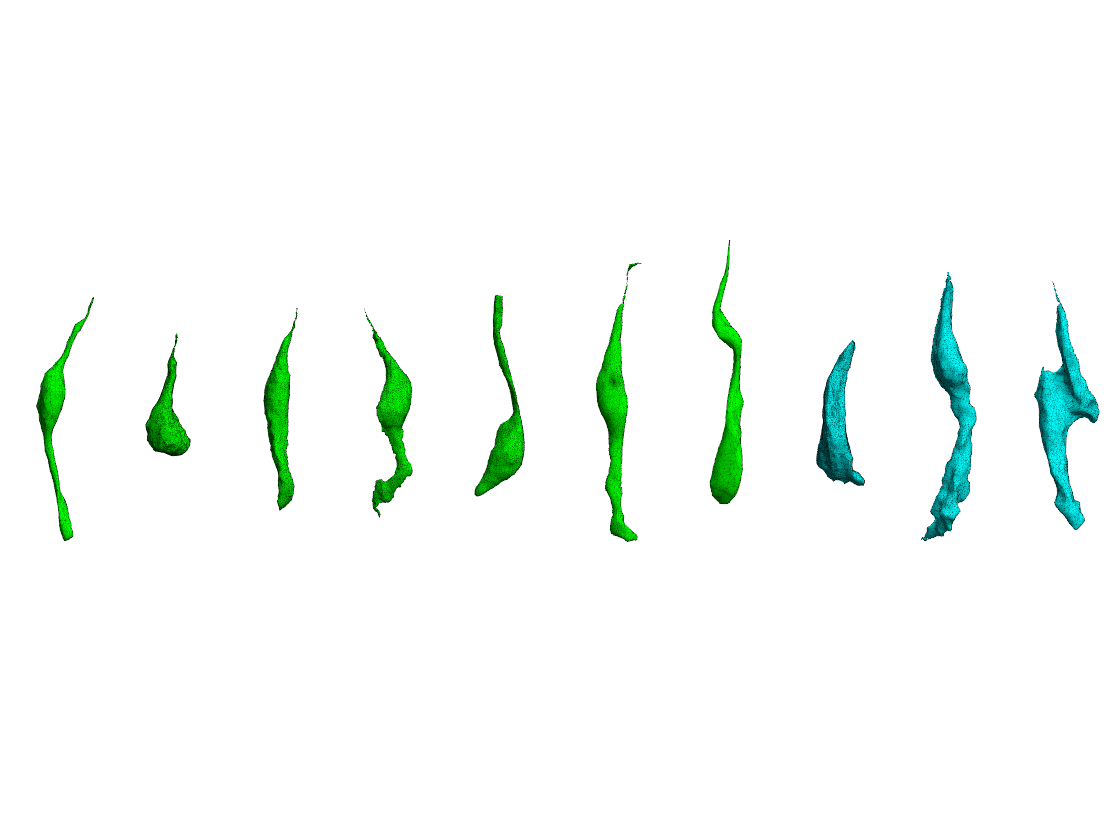

display_cell_by_type(T,"III")

### Type IV

32. TB1_IMMcell08_CM_RKJ. healthy. 191.43
33. TB1_IMMCell09_CM_ry. healthy. 350.13
34. TB2 Nucleus_26_cw_IV-ry. healthy. 550.18
35. TB2_T4C-01_cw. healthy. 742.60


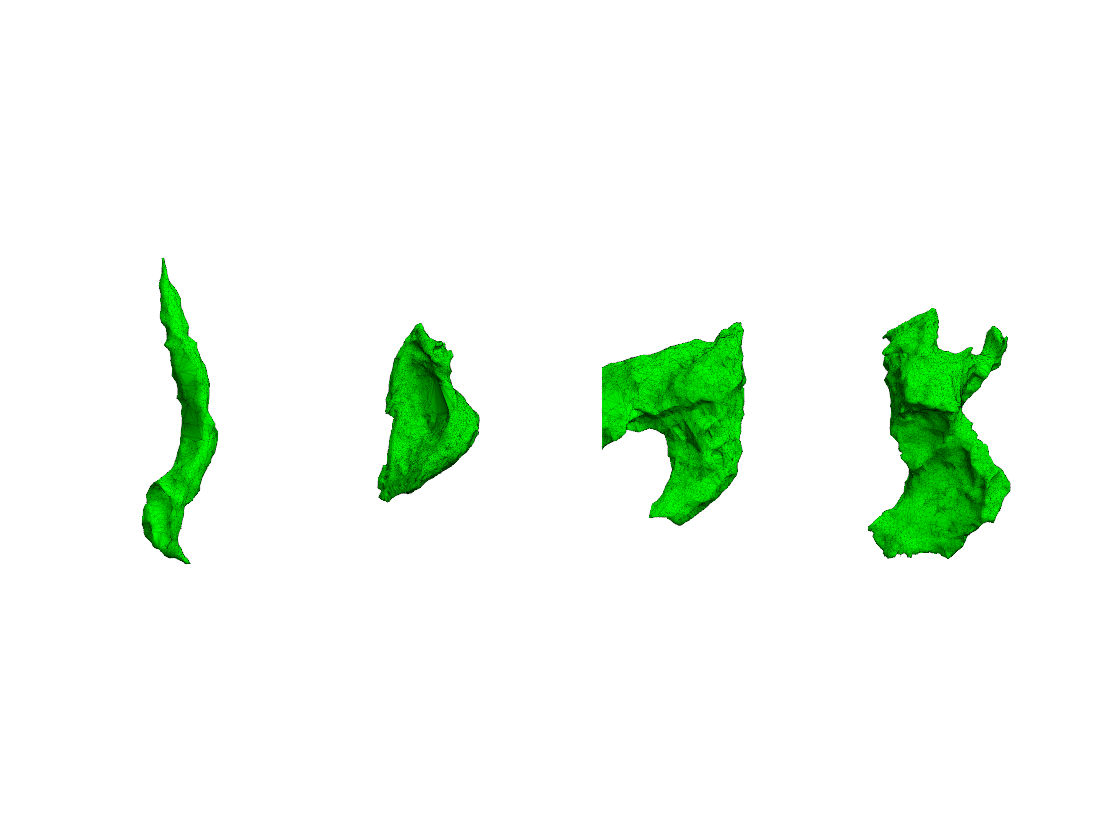

display_cell_by_type(T,"IV")

### Dying Cells

37. TB2_TCdying01. late. 403.60
38. TB2_TCdying02. late. 457.08
40. TB3_TC01. late. 446.93


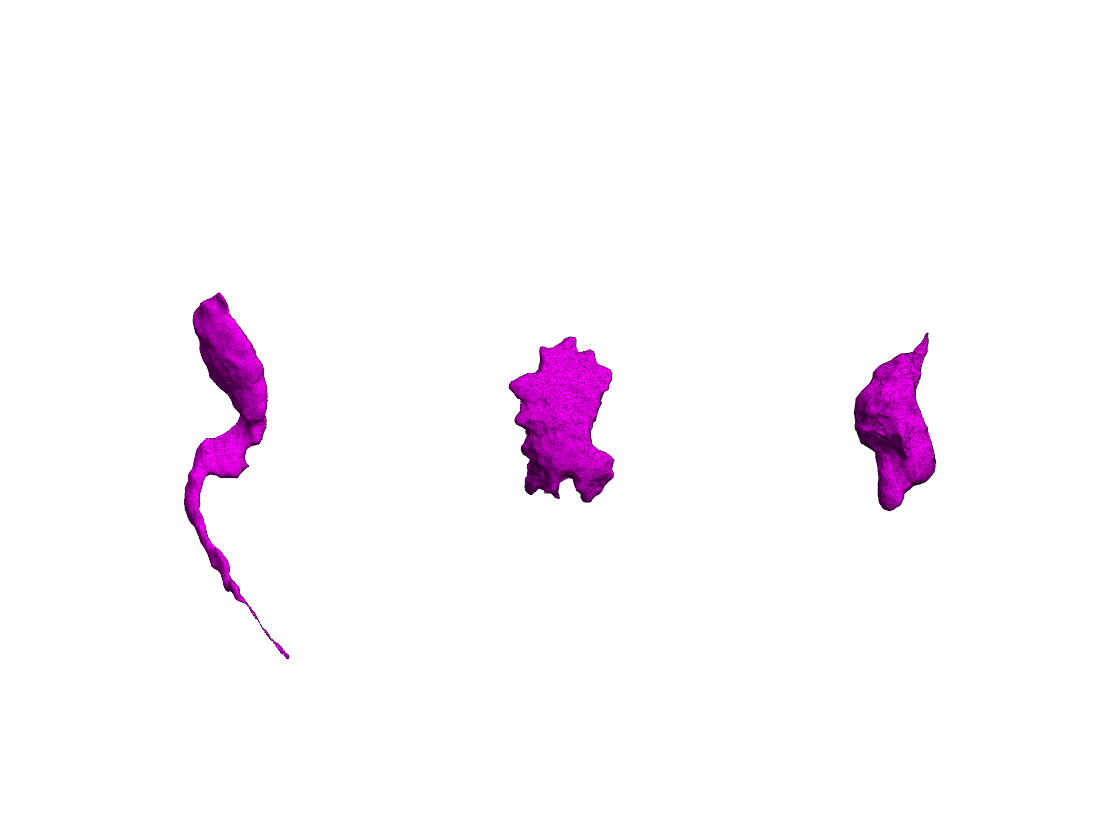

display_cell_by_type(T,"x")

early dying here is a type II cell

writetable(T,"cell_metrics.csv")

## Statistics

mmSetFigPublication 

Default figure color set to white.
Default font size set to 16.0.

groupsummary(T,"Health",["mean","median","range"],"Volume")

ans = 3×5 table
    Health     GroupCount    mean_Volume    median_Volume    range_Volume
    _______    __________    ___________    _____________    ____________

    early          15          1294.4          1310.5           1262.7   
    healthy        27          739.07           664.3           1442.6   
    late            3          435.87          446.93           53.487   


- Some differences between Mean and Median values further confirm non-normality

gs = groupsummary(T,"Health",{@skewness, @kurtosis},"Volume");
gs.Properties.VariableNames(3:4) = {'Skewness','Kurtosis'}

gs = 3×4 table
    Health     GroupCount    Skewness    Kurtosis
    _______    __________    ________    ________

    early          15         0.18799     2.1931 
    healthy        27          0.9871     3.4955 
    late            3        -0.60686        1.5 


- volumes are somewhat skewed 

#### One-sample Kolmogorov-Smirnov test for normality of lysosomal volumes in each cell

h=1 means not normal

kstest(T.Volume)

ans = logical
   1


- volumes are not normally distributed

### Volume of Cell by Type

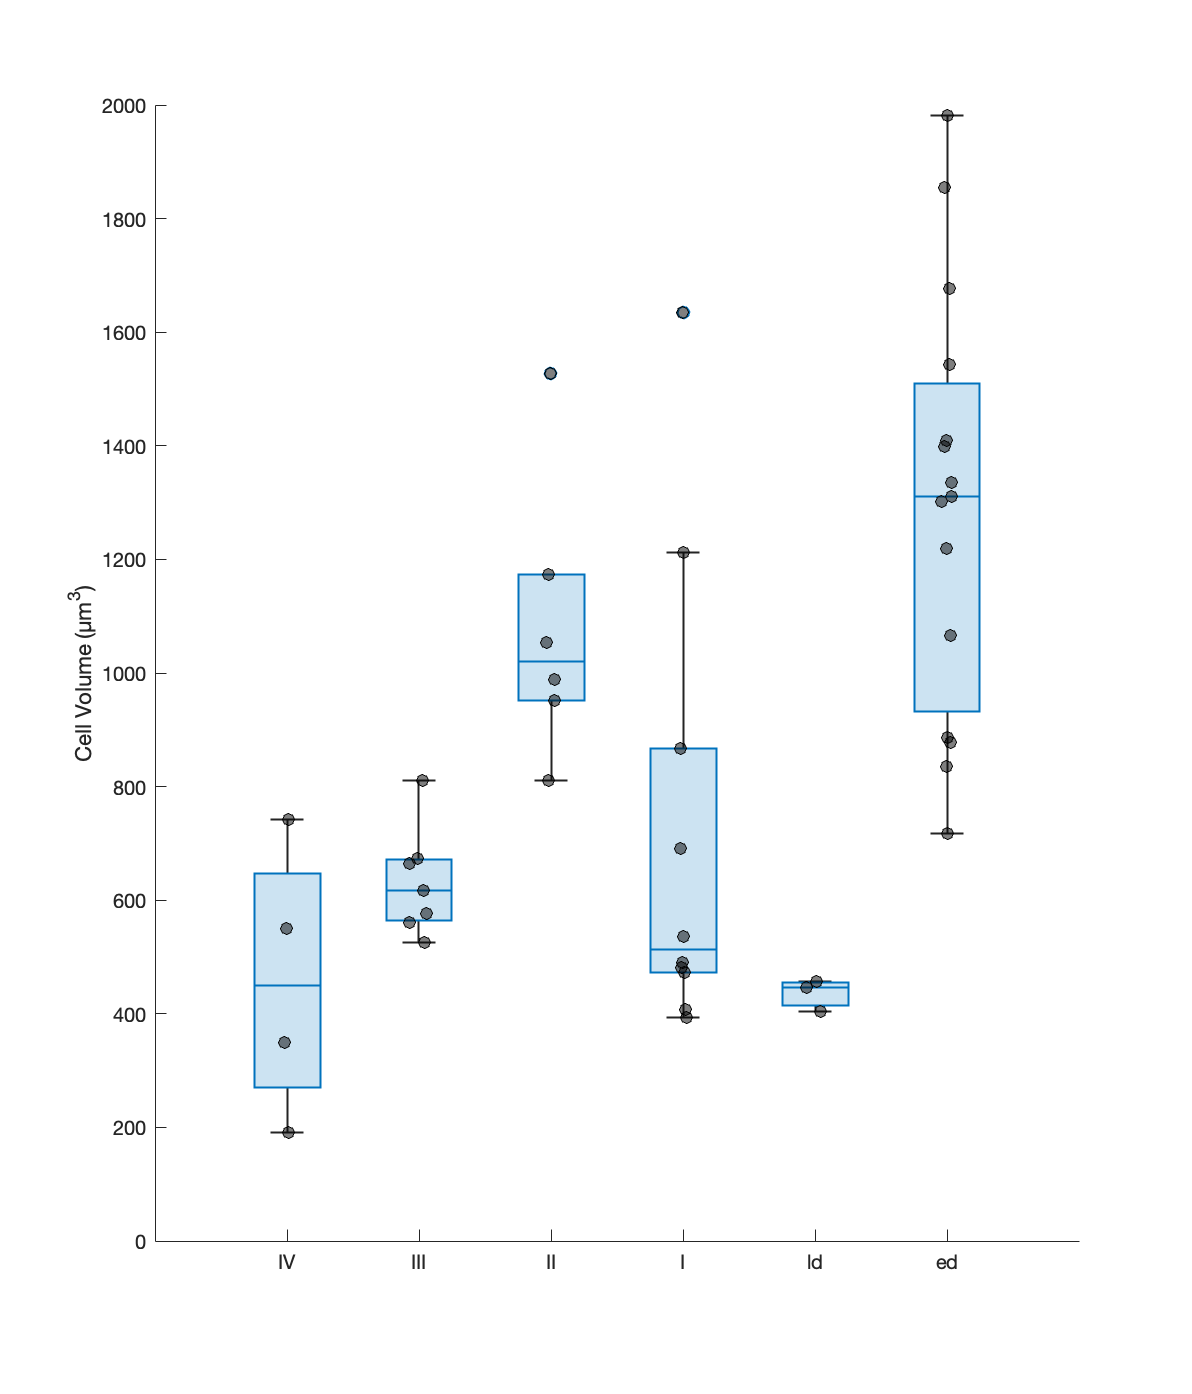

mmfig;

tiledlayout("horizontal")

g = T.PlotSort;
y = T.Volume;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel('Cell Volume (µm^3)')

### Groups by Type and Health

g1 = string(T.Type);
g2 = string(T.Health);
gc = categorical(g1+g2);

gc = 45×1 categorical array
     IIIhealthy 
     IIearly 
     IIhealthy 
     Ihealthy 
     IIIhealthy 
     Ihealthy 
     Ihealthy 
     Ihealthy 
     Ihealthy 
     IIearly 
     IIearly 
     Ihealthy 
     IIearly 
     IIIearly 
     Ihealthy 
     IVhealthy 
     IVhealthy 
     IIearly 
     IIearly 
     IIearly 
     Ihealthy 
     IVhealthy 
     Ihealthy 
     Ihealthy 
     IIearly 
     IIearly 
     IIhealthy 
     IIhealthy 
     IIhealthy 
     IIhealthy 


gs = groupsummary(T,"PlotSort","median","Volume")

gs = 6×3 table
    PlotSort    GroupCount    median_Volume
    ________    __________    _____________

      IV             4           450.13    
      III            7           616.43    
      II             6           1021.1    
      I             10           513.22    
      ld             3           446.93    
      ed            15           1310.5    


### Nonparametric Anova

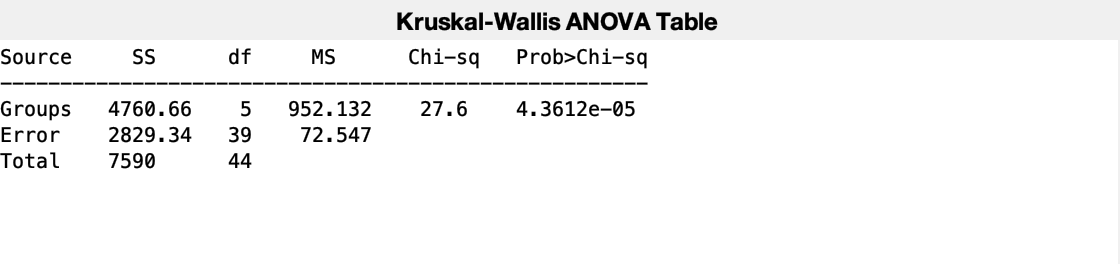

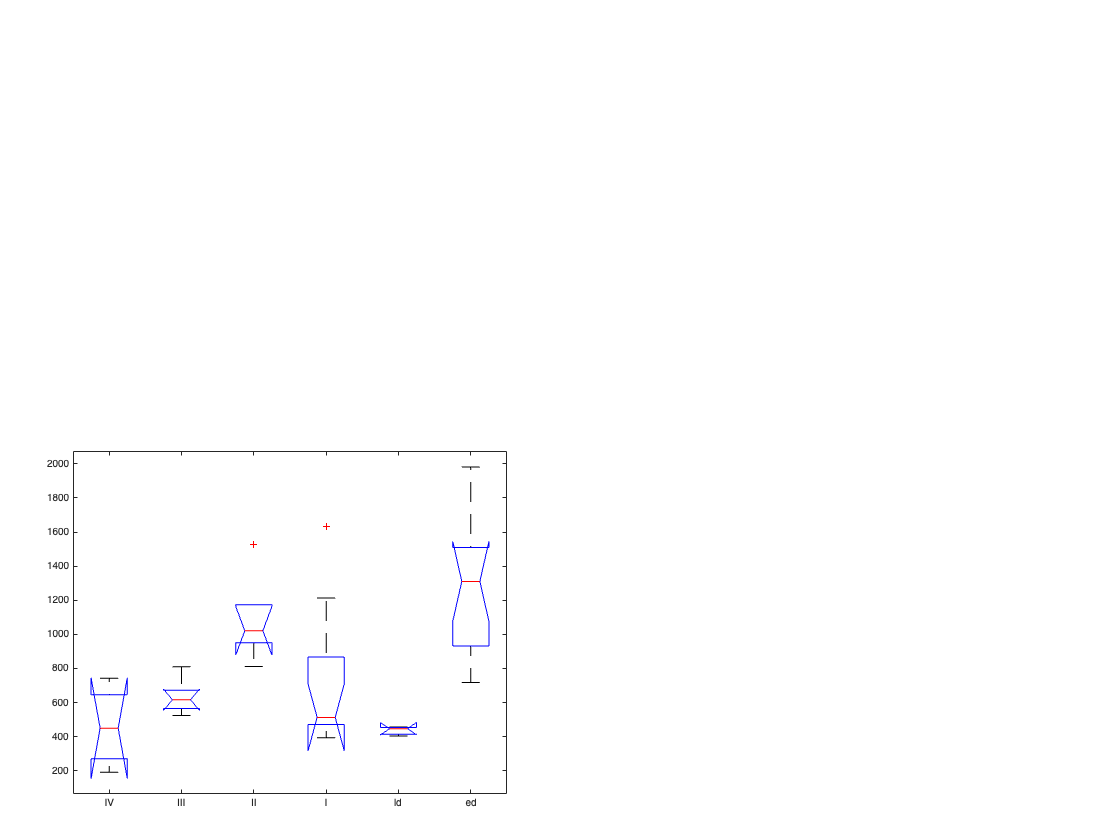

p =    4.3612e-05


tbl = 4×6 cell array
    {'Source'}    {'SS'    }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[4760.7]}    {[ 5]}    {[  952.13]}    {[  27.598]}    {[ 4.3612e-05]}
    {'Error' }    {[2829.3]}    {[39]}    {[  72.547]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[  7590]}    {[44]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 6 10 3 15]
       source: 'kruskalwallis'
    meanranks: [9.25 16.143 30.333 16.6 5.6667 34.667]
         sumt: 0


[p,tbl,stats] = kruskalwallis(y,g)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


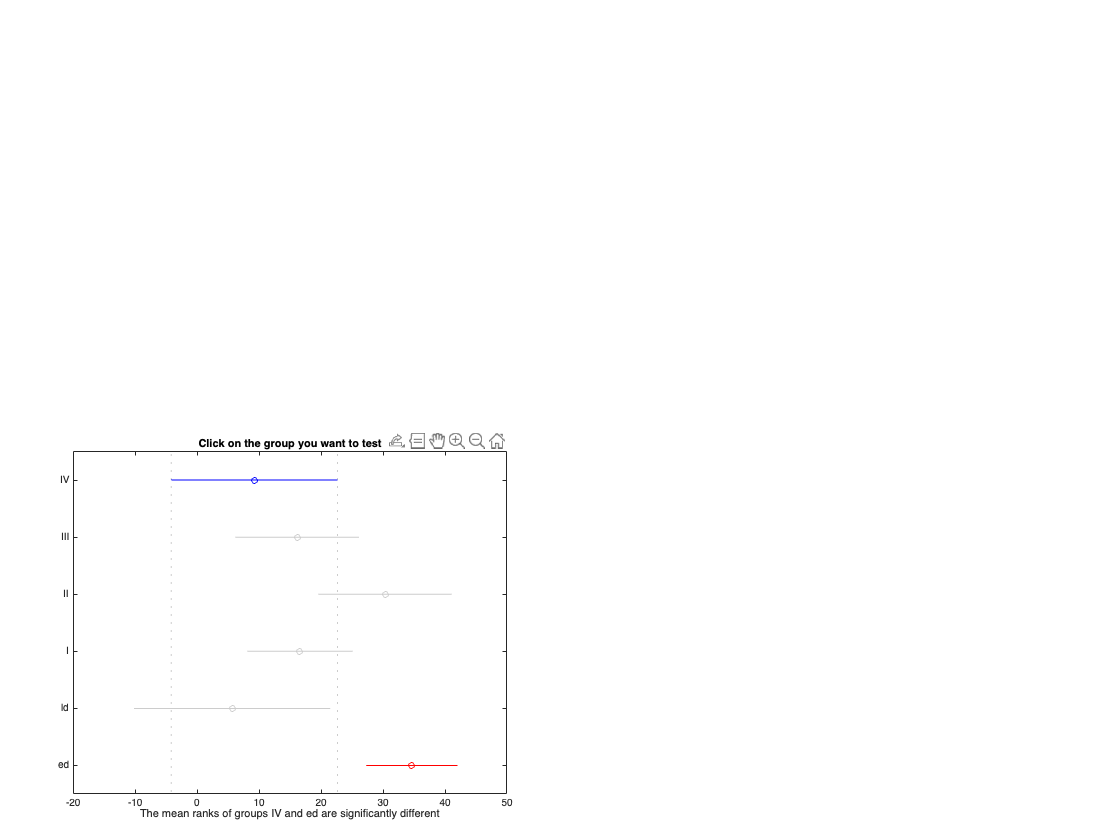

[c,~,~,gnames]= multcompare(stats);

tbl = array2table(c,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"]);
tbl.("Group A")=gnames(tbl.("Group A"));
tbl.("Group B")=gnames(tbl.("Group B"))

tbl = 15×6 table
    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value 
    _______    _______    ___________    ________    ___________    _________

    {'IV' }    {'III'}      -30.352       -6.8929       16.566        0.96059
    {'IV' }    {'II' }      -45.243       -21.083       3.0762        0.12789
    {'IV' }    {'I'  }      -29.493         -7.35       14.793        0.93449
    {'IV' }    {'ld' }      -25.003        3.5833       32.169        0.99924
    {'IV' }    {'ed' }      -46.478       -25.417      -4.3549      0.0076991
    {'III'}    {'II' }      -35.013        -14.19       6.6324        0.37635
    {'III'}    {'I'  }      -18.902      -0.45714       17.987              1
    {'III'}    {'ld' }      -15.351        10.476       36.304        0.8576

### Report Post hoc mann whitney

s = sprintf('%s U(Ndying=%d, Nhealthy=%d)=%1.2f,z=%1.2f, p=%0.3e.',...
    s,...
    numel(yd),...
    numel(yh),...
    stats.ranksum,...

ans =      0.016667


    stats.zval, ...
    p);
disp(s)
clipboard("copy",s) % copy to clipboard

### Pairwise Comparison

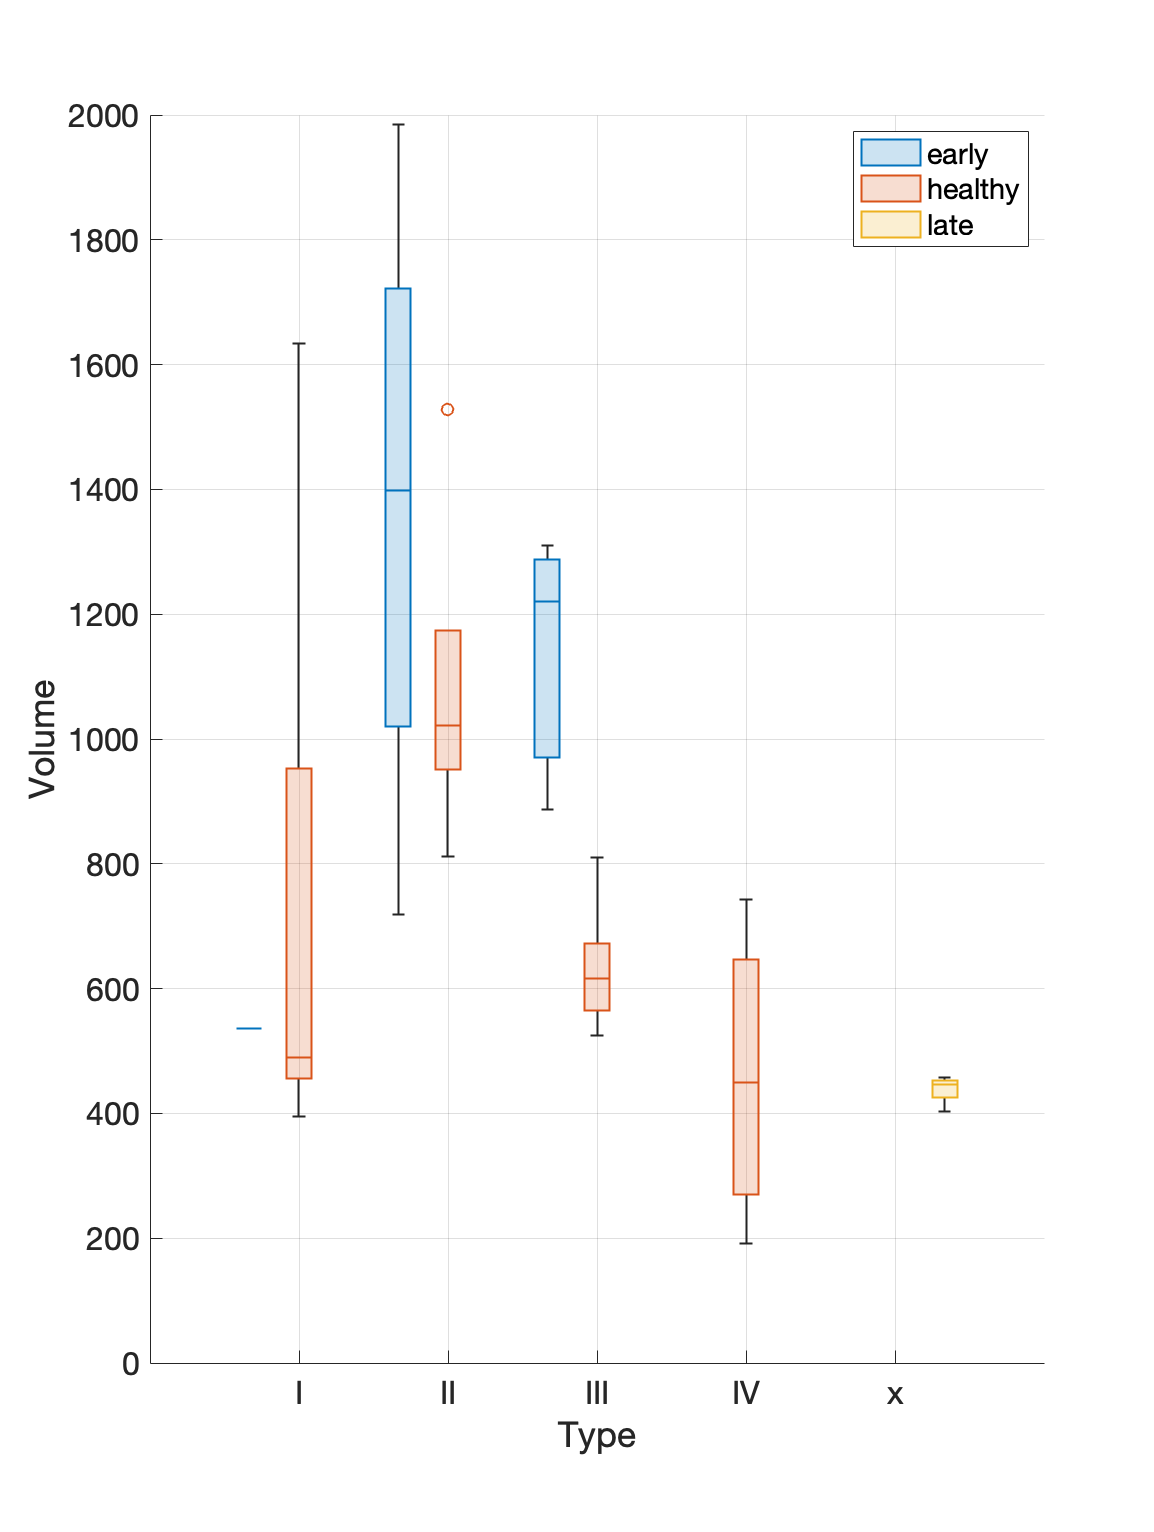

la1 = T.Type == "III" & T.Health == "healthy";
lam2 = T.Type == "III" & T.Health == "early";
y = T.Volume;


ranksum(y(la1), y(la2))

t = 19×8 table
            Cell             Type    Health     Volume    SurfaceArea      SAV                Filename              PlotSort
    _____________________    ____    _______    ______    ___________    _______    ____________________________    ________

    "TB1_T2C11"               II     early      717.99      563.37        1.2744    "TB1_T2C11_mp.obj"                 ed   
    "TB2_T2C-12_cw"           II     healthy    810.96      932.29       0.86986    "TB2_T2C-12_cw_mp.obj"             II   
    "TB1_T2C05"               II     early      835.16      1231.3       0.67826    "TB1_T2C05_as.obj"                 ed   
    "TB1_T2C06"               II     early      878.17      655.73        1.3392    "TB

### Volume of Cell by Type, Grouped by Health

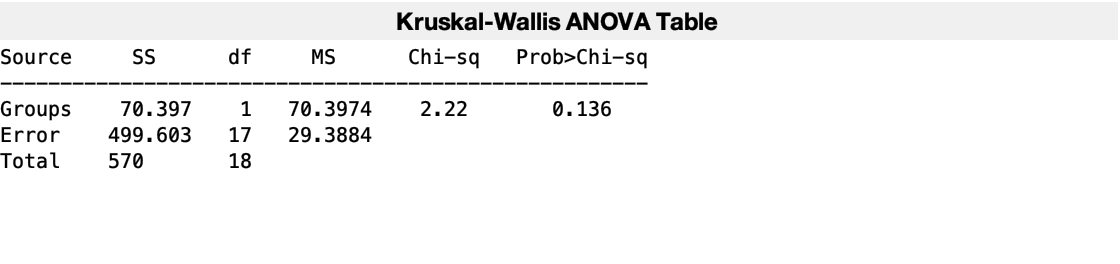

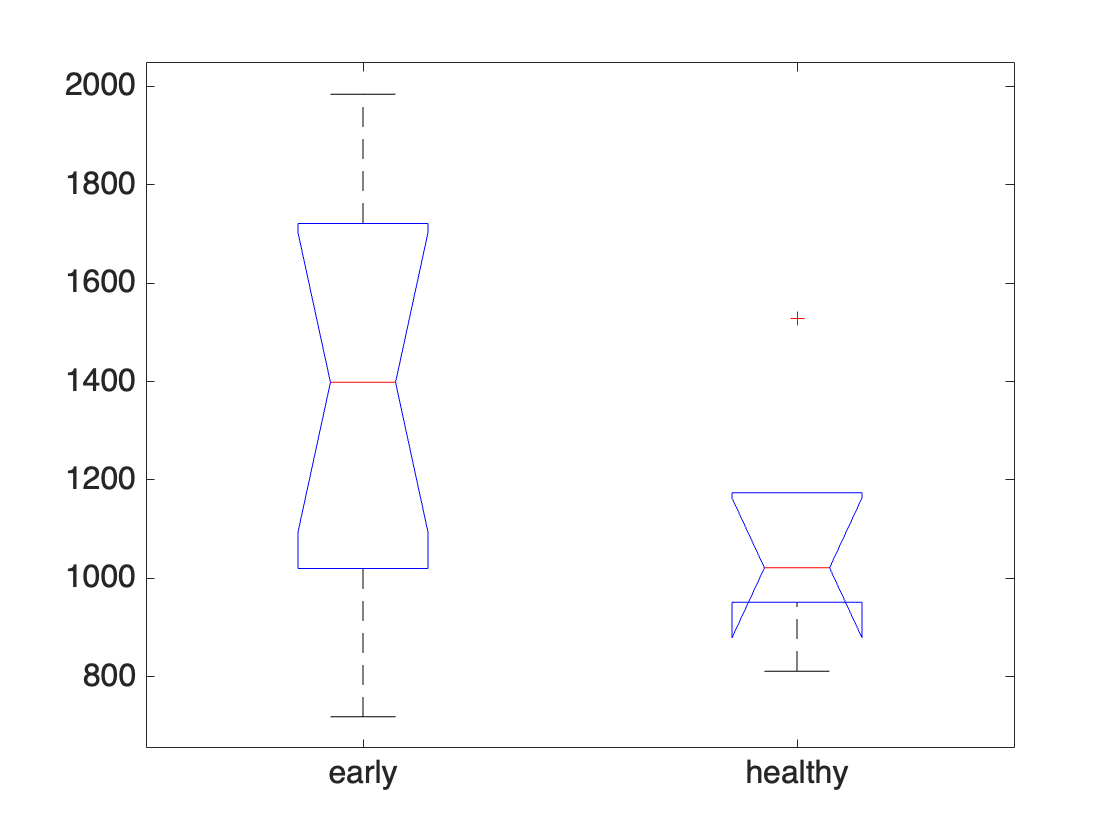

p =       0.13596


tbl = 4×6 cell array
    {'Source'}    {'SS'    }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[70.397]}    {[ 1]}    {[  70.397]}    {[  2.2231]}    {[    0.13596]}
    {'Error' }    {[ 499.6]}    {[17]}    {[  29.388]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[   570]}    {[18]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {2×1 cell}
            n: [13 6 0]
       source: 'kruskalwallis'
    meanranks: [11.308 7.1667 NaN]
         sumt: 0


mmfig;
boxchart(T.Type,T.Volume,GroupByColor=T.Health)
legend

grid on
xlabel('Type'); ylabel('Volume')

t = T(T.Type=="II",:)

g = t.Health;
y = t.Volume;
[p,tbl,stats] = kruskalwallis(y,g)

Error using anova1 (line 97)
X and GROUP must have the same length.

Error in kruskalwallis (line 48)
[p,anovatab,stats] = anova1('kruskalwallis', varargin{:});

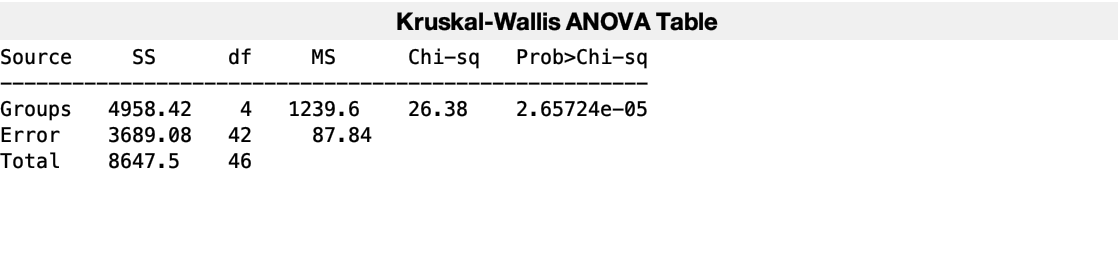

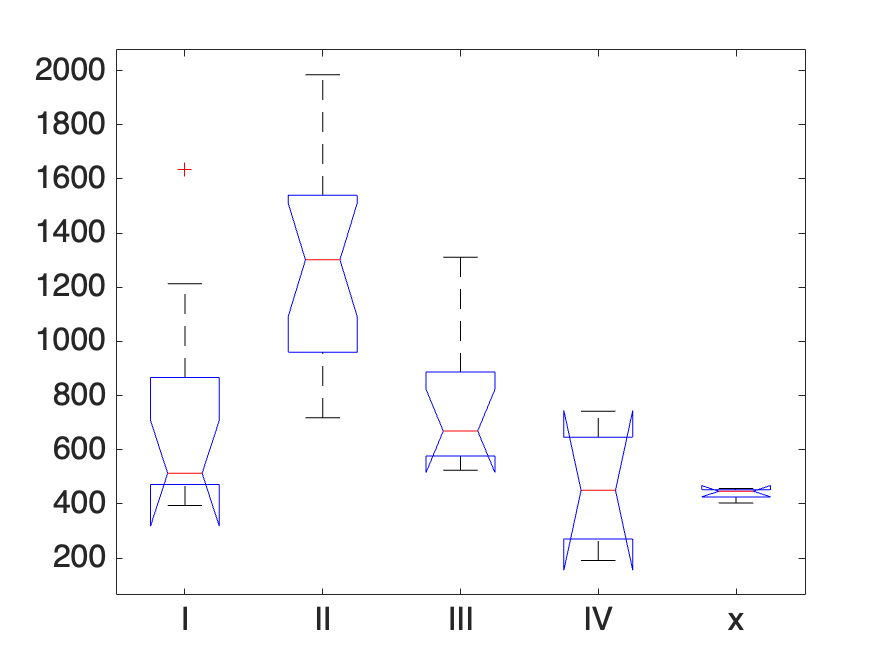

p =    2.6572e-05


tbl = 4×6 cell array
    {'Source'}    {'SS'    }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[4958.4]}    {[ 4]}    {[  1239.6]}    {[  26.376]}    {[ 2.6572e-05]}
    {'Error' }    {[3689.1]}    {[42]}    {[  87.835]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[8647.5]}    {[46]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {5×1 cell}
            n: [10 19 10 4 4]
       source: 'kruskalwallis'
    meanranks: [17.4 35.263 22 9.75 6.25]
         sumt: 6


g1 = T.Type;

g2 = T.Health;

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


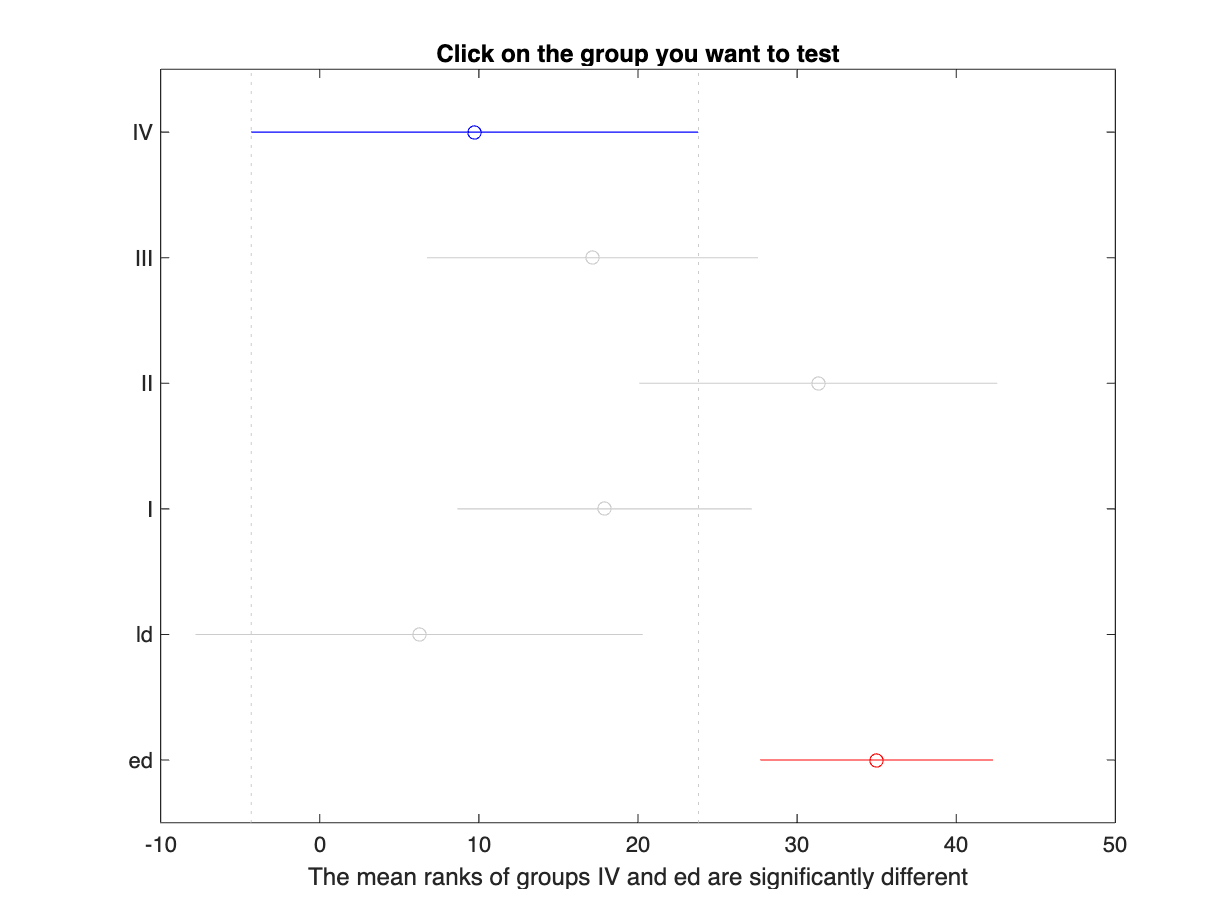

y = T.Volume;


[p,tbl,stats] = kruskalwallis(y,{g1 g2})

[p,tbl,stats]=kruskalwallis(y,g)

c = multcompare(stats);

## Local Functions

function display_cell_by_type(T,type)

arguments
    T table % cellT or dyingT
    type {mustBeText}
end


la = T.Type == type;
count = nnz(la);
idc = find(la)';
colorD = dictionary(["healthy" "early" "late"], ["g" "c" "m"]);

meshFolder = T.Properties.UserData.meshPath;

figure(Visible='on',Color='w')
tiledlayout(1,count,"TileSpacing","none","Padding","tight")
for n=idc
    
    fullpath = fullfile(meshFolder, T.Filename(n));
    cellName = T.Cell(n);

        mesh = readSurfaceMesh(fullpath);
        nexttile
        
        plotCellMesh(mesh,colorD(T.Health(n)))

        % simplify(mesh);
        %  % simplify(mesh,SimplificationMethod="quadric-decimation")
        %  % simplify(mesh,SimplificationMethod="vertex-clustering")
        % 
        % 
        % patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
        %     FaceColor=colorD(T.Health(n)), ...
        %     edgeAlpha = 0.1)
        % axis equal off
        % xlim([-10 10])
        % ylim([-10 10])
        % zlim([-50 50])
        % 
        % set(gca,CameraTarget=[0,0,0])
        % view([0 0])
        % 
        % % lightangle(45,30);
        % lighting gouraud
        % material dull
        % 
        % % camera position - adds two opposing lights for better visibility
        % camlight('right')
        % camorbit(180,0,'data',[0 0 1])
        % camlight('right')

        fprintf('%d. %s. %s. %1.2f\n', n, cellName, T.Health(n), T.Volume(n))
    % catch
    %     fprintf('%d. %s did not print.\n',n,cellName)
    % end

end
end

function display_surfaceMesh(paths, cell)
    fullpath = fullfile(paths.cellMesh,cell+"_manifold.obj");
    mesh = readSurfaceMesh(fullpath);
    surfaceMeshShow(mesh)
end
